close all; clear all;
% -- PROPERTIES ------------------------------------------------
dens=1.103423871721158;     % Reference density [kg/m3]
mu=1.835086578440896e-05;   % Reference dynamic viscosity [Pa·s]

% -- BOUNDARY LAYER POST-PROCESSING ----------------------------
[x,y,yp,u,u_c,u_b,u_tau,tau,d,d_star,theta,Re_b,Re_tau,Re_theta,ytot,Var] = f_UY_properties(dens,mu,"Data_CrossSections/Medium/XY-symmetry.txt");

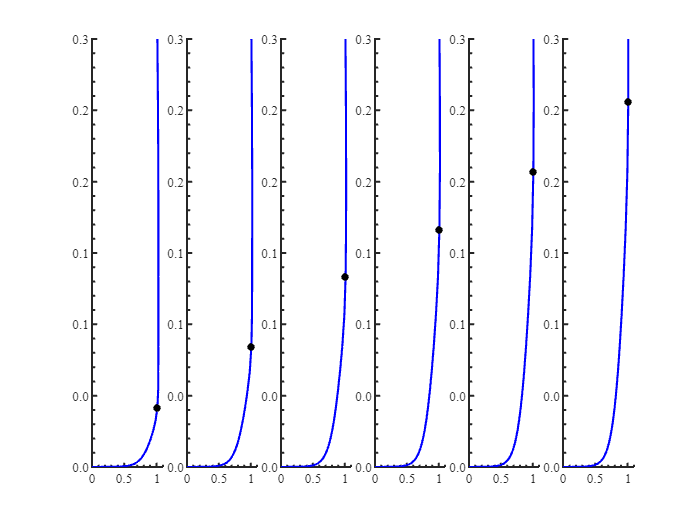

% -- BOUNDARY LAYER VISUALIZATION ------------------------------
f_BL_plots(y(:,1),u(:,:,1),u_c,d(:,:,1));

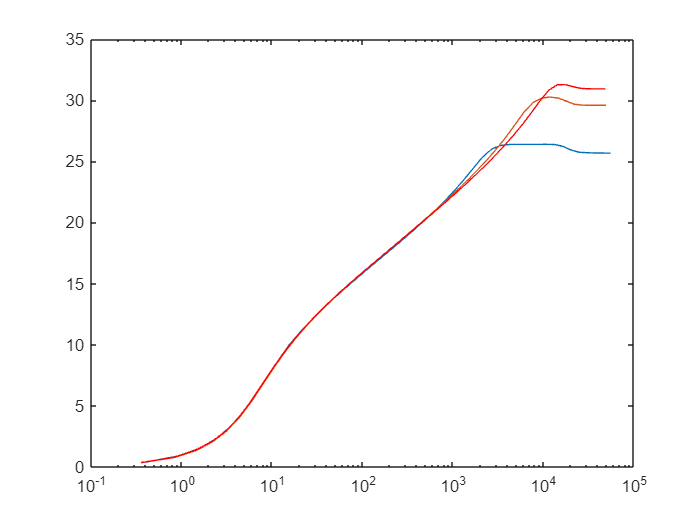

figure;
semilogx(yp(1,:,1),u(1,:,1)/u_tau(1));
hold on;
semilogx(yp(85,:,1),u(85,:,1)/u_tau(85));
hold on;
semilogx(yp(end,:,1),u(end,:,1)/u_tau(end),'r');
hold off;

% -- SYMMETRY SECTION VISUALIZATION ----------------------------
% [Xm,Ym]=meshgrid(x/x(end),ytot/ytot(end));
% 
% figure;
% subplot(3,1,1);
% hAxes = gca;
% contourf(Xm,Ym,transpose(Var(:,:,1)),100,'LineStyle','none');
% colormap gray;
% colorbar('northoutside');
% colourRange = caxis(hAxes);
% cbar.Ticks = linspace( colourRange(1), colourRange(end), 7);
% tix = cbar.Ticks; 
% cbar.TickLabels = compose('%2.2ff',tix); 
% ax = gca;
% ax.LineWidth = 1.2;
% ax.XAxis.FontSize = 12;
% ax.YAxis.FontSize = 12;
% 
% 
% subplot(3,1,2);
% hAxes = gca;
% contourf(Xm,Ym,transpose(Var(:,:,3)),100,'LineStyle','none');
% colormap gray;
% cbar = colorbar('northoutside');
% colourRange = caxis(hAxes);
% cbar.Ticks = linspace( colourRange(1), colourRange(end), 7);
% tix = cbar.Ticks; 
% cbar.TickLabels = compose('%2.2f',tix); 
% ax = gca;
% ax.LineWidth = 1.2;
% ax.XAxis.FontSize = 12;
% ax.YAxis.FontSize = 12;
% 
% subplot(3,1,3);
% plot(x,u_c,"LineStyle","-","Color","k","LineWidth",1.25);
% set(gca,'yticklabel',num2str(get(gca,'ytick')','%.1f'))
% fontname(gca,"Times New Roman")
% set(gcf,'color','w');
% set(gca,'XMinorTick','on','YMinorTick','on');
% ax = gca;
% ax.LineWidth = 1.2;
% ax.XAxis.FontSize = 12;
% ax.YAxis.FontSize = 12;


% -- COMPARISON WITH THE LITERATURE ----------------------------
Re_1410=csvread("Literature/DNS_Schlatter_1410.txt");
Re_3970=csvread("Literature/DNS_Schlatter_3970.txt");
figure;
semilogx(yp(31,:,1),u(31,:,1)/u_tau(31,1),'LineStyle','-','Color','r');yp(31,2,1)

ans = 0.3835

hold on;
semilogx(Re_1410(:,3),Re_1410(:,4),'LineStyle','-.','Color','r');
hold on;
semilogx(yp(41,:,1),u(41,:,1)/u_tau(41,1),'LineStyle','-','Color','b');yp(41,2,1)

ans = 0.3780

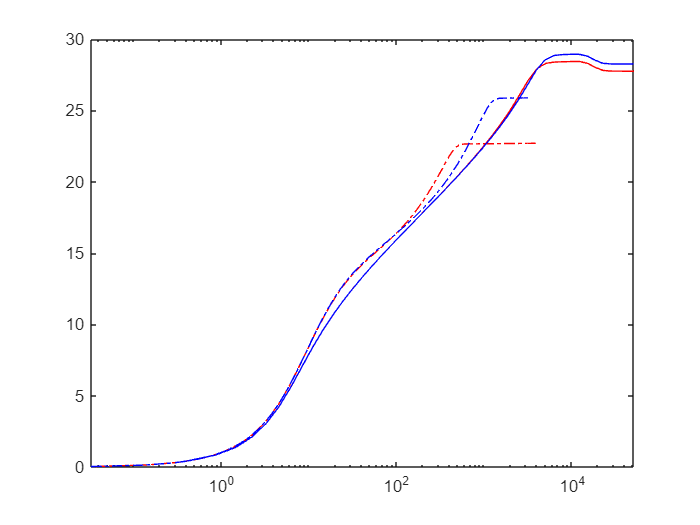

hold on;
semilogx(Re_3970(:,3),Re_3970(:,4),'LineStyle','-.','Color','b');
hold off;
xlim([yp(31,1,1) yp(31,end,1)])